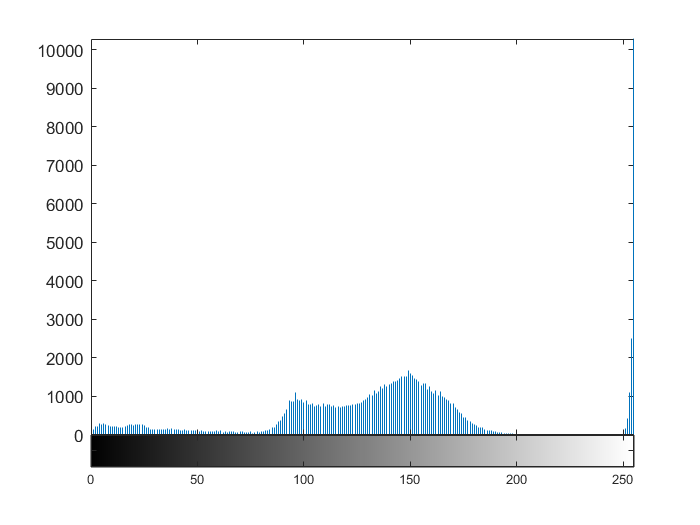

original = imread("ball.jpg");
image = im2gray(original);
imhist(image)

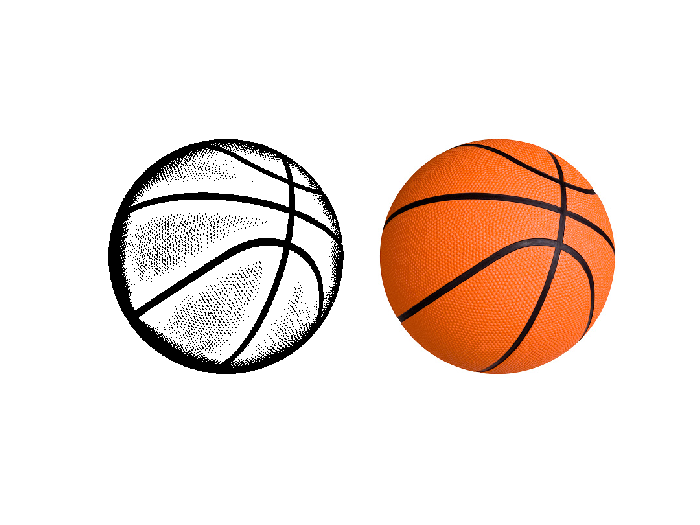

image = imadjust(image);
image = imbinarize(image,"adaptive","ForegroundPolarity","dark");
imshowpair(image,original,"montage")

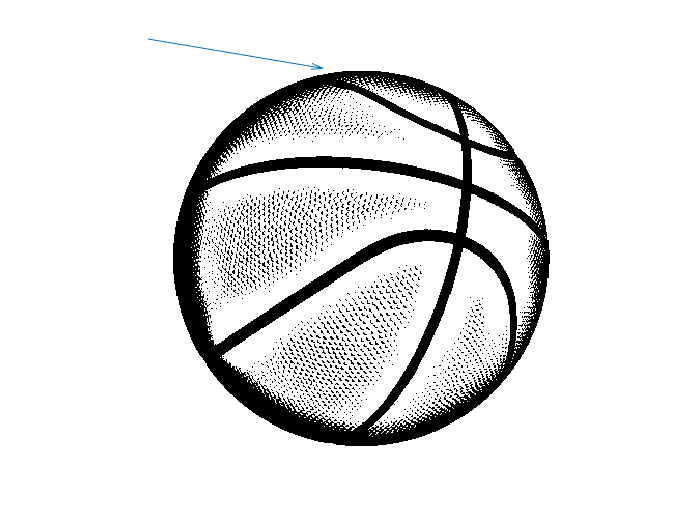

[image_hight, image_width] = size(image);
start_pixel_found = 0;

for i = 1:image_hight
    for j = 1:image_width
        if image(i,j) == 0
            start_pixel_found = 1;
            break;
        end
    end
    if start_pixel_found
        break;
    end
end

starting_pixel = [i j];

imshow(image)
hold on
quiver(0,0,j,i)

offset = [0 -1; -1 -1; -1 0; -1 1; 0 1; 1 1; 1 0; 1 -1];
switch_indx = [7 7 1 1 3 3 5 5];
offset_indx = 1;

p = starting_pixel;
c = p + offset(offset_indx,:);

B = starting_pixel;


steps = 0;
% max_steps = 2000;
% && steps < max_steps

while ~isequal(c, starting_pixel) 
    steps = steps +1;
    if image(c(1), c(2)) == 0
        B = [B; c];
        p = c;
        offset_indx = switch_indx(offset_indx);
        c = p + offset(offset_indx,:);
    else
        if offset_indx == 8
            offset_indx = 1;
        else
            offset_indx = offset_indx + 1;
        end
        c = p + offset(offset_indx,:);
    end
end

imshow(image)
steps

steps = 3501

B

B =     32   191
    32   192
    32   193
    32   194
    32   195
    32   196
    32   197
    32   198
    32   199
    32   200


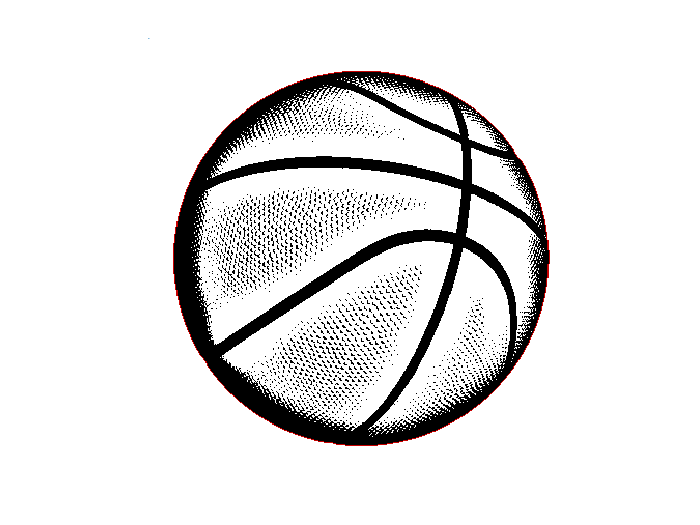

result = 255 * repmat(uint8(image),1 ,1, 3); % covert binary image to rgb

for i = 1:size(B,1)
    result(B(i,1),B(i,2)) = 200;
end

imshow(result)